% generate wav


fBegin = 2000;
fEnd = 6000;
frequencyOfSample = 48000

frequencyOfSample = 48000

chirpTimeMs = 50   %ms

chirpTimeMs = 50

prepareTimeMs = 50

prepareTimeMs = 50


chirpSample = floor(chirpTimeMs * frequencyOfSample / 1000)

chirpSample = 2400

prepareSample = floor(prepareTimeMs * frequencyOfSample / 1000)

prepareSample = 2400


t1 = (0:prepareSample - 1) / frequencyOfSample

t1 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010


y1 = sin(2 * pi * fBegin * t1)

y1 =          0    0.2588    0.5000    0.7071    0.8660    0.9659    1.0000    0.9659    0.8660    0.7071    0.5000    0.2588    0.0000   -0.2588   -0.5000   -0.7071   -0.8660   -0.9659   -1.0000   -0.9659   -0.8660   -0.7071   -0.5000   -0.2588   -0.0000    0.2588    0.5000    0.7071    0.8660    0.9659    1.0000    0.9659    0.8660    0.7071    0.5000    0.2588    0.0000   -0.2588   -0.5000   -0.7071   -0.8660   -0.9659   -1.0000   -0.9659   -0.8660   -0.7071   -0.5000   -0.2588   -0.0000    0.2588



t2 = (0:chirpSample) / frequencyOfSample

t2 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010


k = (fEnd - fBegin) * 1000 / chirpTimeMs

k = 80000

y2 = sin(2 * pi * (fBegin * t2 + 1/2 * k * t2 .* t2))

y2 =          0    0.2589    0.5004    0.7078    0.8669    0.9666    1.0000    0.9645    0.8625    0.7008    0.4905    0.2460   -0.0157   -0.2766   -0.5184   -0.7242   -0.8796   -0.9736   -0.9994   -0.9550   -0.8434   -0.6723   -0.4536   -0.2027    0.0628    0.3240    0.5624    0.7610    0.9056    0.9856    0.9952    0.9335    0.8049    0.6183    0.3871    0.1278   -0.1409   -0.3996   -0.6297   -0.8142   -0.9397   -0.9969   -0.9815   -0.8945   -0.7420   -0.5350   -0.2886   -0.0208    0.2487    0.5001



t = [t1, t2 + prepareSample / frequencyOfSample]

t =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010


y = [y1, y2]

y =          0    0.2588    0.5000    0.7071    0.8660    0.9659    1.0000    0.9659    0.8660    0.7071    0.5000    0.2588    0.0000   -0.2588   -0.5000   -0.7071   -0.8660   -0.9659   -1.0000   -0.9659   -0.8660   -0.7071   -0.5000   -0.2588   -0.0000    0.2588    0.5000    0.7071    0.8660    0.9659    1.0000    0.9659    0.8660    0.7071    0.5000    0.2588    0.0000   -0.2588   -0.5000   -0.7071   -0.8660   -0.9659   -1.0000   -0.9659   -0.8660   -0.7071   -0.5000   -0.2588   -0.0000    0.2588


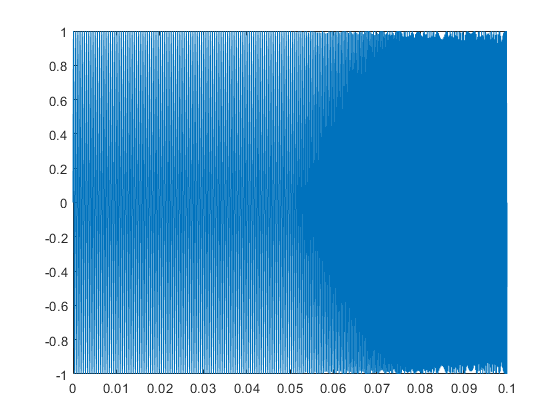


plot(t, y)


spectrogram(y, 256, 250, 256, 44100)

'spectrogram' 需要 Signal Processing Toolbox。


fName = "chirp_for_experiment.wav"
audiowrite(fName, y, frequencyOfSample)
info = audioinfo(fName)
